% This is a script to show the raw timeseries BOLD signal change and Frame
% Displacement for CONN paper
% Written by Violet Zhou 
% March 2025

%keyboard

% Section I = organize the outliers 
% I abandoned this section, since we can use more flexible threshold
% You could only look at the outliers according to your settings in the
% CONN; however, we use both 0.2 and 0.45 and I figured out how to process
% when we have multiple threshold
% Please refer to section III
% First we need to look at the outliers, if there are too much outlier
% slices, (data <4 minutes after deleting the slices, we will exclude them)

% Set the folder
cd('/nfs/tpolk/mind/Conn_2024/Conn_2025/Prep/W2/Functional');

% Check the mindys
% cd('/nfs/tpolk/mind/Conn_2024/Conn_2025/Prep/Young/Functional');
% cd('/nfs/tpolk/mind/Conn_2024/Conn_2025/Prep/Young_0.2/Functional');


% Get the list of outlier files
outlier_files_1 = dir('art_regression_outliers_aum*.mat');

% Initialize arrays to store results
subject_ids = {};
num_outliers = [];

% Loop through each file
for i = 1:length(outlier_files_1)
    % Load the data
    file_name = outlier_files_1(i).name;
    data = load(file_name);
    
    % Get the variable name (assuming only one variable per file)
    var_names = fieldnames(data);
    outlier_matrix = data.(var_names{1});
    
    % Extract 'mindo###' or 'mindb###' from the filename
    token = regexp(file_name, 'au(mind[oby]\d+)_run', 'tokens');
    if ~isempty(token)
        subject_id = token{1}{1};
    else
        subject_id = 'unknown';
    end

    % Count the number of outliers (columns)
    n_outliers = size(outlier_matrix, 2);

    % Store
    subject_ids{end+1,1} = subject_id;
    num_outliers(end+1,1) = n_outliers;
end

% Create a summary table
summary_table = table(subject_ids, num_outliers, ...
    'VariableNames', {'SubjectID', 'NumOutliers'});

% Display the result
disp(summary_table);

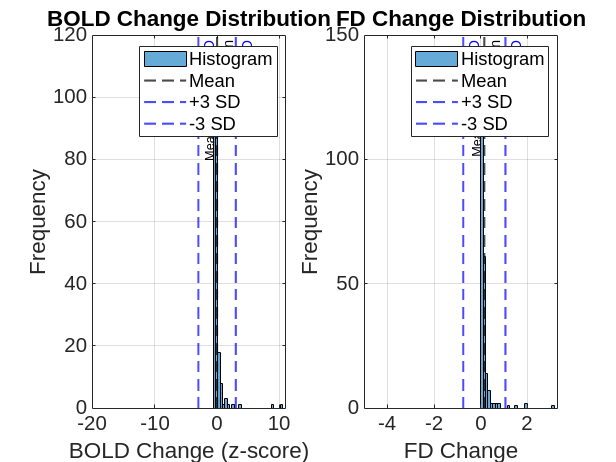

% Section II plot singel subject QC
% subject_id = "mindo152"; % <- update this per subject
% Look into subject's individual data for FD:
% Set working directory
% cd('/nfs/tpolk/mind/Conn_2024/Conn_2025/Prep/W1/Functional');

% Load the specific file
BOLD_FD_file = dir('art_regression_timeseries_aumindy147_run_01.mat');
data = load(BOLD_FD_file.name);

% Get the variable inside the .mat file
var_names = fieldnames(data);
matrix = data.(var_names{1});  % Expected size: 240x2

% Extract BOLD and FD change
bold_change = matrix(:, 1);
fd_change = matrix(:, 2);

bold_change_z = zscore(bold_change);

% Calculate stats
bold_mean = mean(bold_change_z);
bold_std = std(bold_change_z);

fd_mean = mean(fd_change);
fd_std = std(fd_change);

% Plot histograms side by side
figure;

% ---- BOLD Plot ----
subplot(1, 2, 1);
histogram(bold_change_z, 30);
xlabel('BOLD Change (z-score)');
ylabel('Frequency');
title('BOLD Change Distribution');
grid on;
hold on;
xline(bold_mean, 'k--', 'LineWidth', 1.5, 'Label', 'Mean');
xline(bold_mean + 3*bold_std, 'b--', 'LineWidth', 1.5, 'Label', '+3 SD');
xline(bold_mean - 3*bold_std, 'b--', 'LineWidth', 1.5, 'Label', '-3 SD');
% Annotate mean value
ymax = ylim;
text(bold_mean, ymax(2)*0.9, sprintf('Mean = %.4f', bold_mean), ...
     'Rotation', 90, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 9);

legend('Histogram', 'Mean', '+3 SD', '-3 SD');

% ---- FD Plot ----
subplot(1, 2, 2);
histogram(fd_change, 30);
xlabel('FD Change');
ylabel('Frequency');
title('FD Change Distribution');
grid on;
hold on;
xline(fd_mean, 'k--', 'LineWidth', 1.5, 'Label', 'Mean');
xline(fd_mean + 3*fd_std, 'b--', 'LineWidth', 1.5, 'Label', '+3 SD');
xline(fd_mean - 3*fd_std, 'b--', 'LineWidth', 1.5, 'Label', '-3 SD');
% Annotate mean value
ymax = ylim;
text(fd_mean, ymax(2)*0.9, sprintf('Mean = %.4f', fd_mean), ...
     'Rotation', 90, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 9);

legend('Histogram', 'Mean', '+3 SD', '-3 SD');

% Section III = FD-based QC (June25 Updated: to get the trait_outliers table) 
% Organize the FD and BOLD signal change for each individua;
% Set working directory
% cd('/nfs/tpolk/mind/Conn_2024/Conn_2025/Prep/W2/Functional');
% cd('/nfs/tpolk/mind/Conn_2024/Conn_2025/Prep/Young/Functional');
% cd('/nfs/tpolk/mind/Conn_2024/Conn_2025/Prep/Young_0.2/Functional');
cd('/nfs/tpolk/mind/Conn_2024/Conn_2025/All_W1_JUNE25/All_W1_JUNE25_with_outliers/Functional_Connectivity');

% Get all potential files first
all_files = dir('art_regression_timeseries_au*.mat');

% Initialize results
subject_ids = {};
bold_means = [];
bold_stds = [];
fd_means = [];
fd_stds = [];
thresh_02_counts = [];
thresh_045_counts = [];

% Loop through each file
for i = 1:length(all_files)
    file_name = all_files(i).name;

    % Only keep files that match *_run_01.mat
    if contains(file_name, '_run_01.mat') && ~isempty(regexp(file_name, 'aumind[oby]\d+', 'once'))
        data = load(file_name);

        % Extract subject ID (e.g., aumindo260 → mindo260)
        token = regexp(file_name, 'aumind[oby]\d+', 'match');
        if ~isempty(token)
            subject_id = extractAfter(token{1}, 2);  % Remove "au"
        else
            subject_id = 'unknown';
        end

        % Extract data matrix
        var_names = fieldnames(data);
        matrix = data.(var_names{1});  % should be 240x2

        % Extract BOLD and FD
        bold_change = matrix(:, 1);
        fd_change = matrix(:, 2);

        % Compute stats
        bold_mean = mean(bold_change);
        bold_std = std(bold_change);
        fd_mean = mean(fd_change);
        fd_std = std(fd_change);

        % Identify BOLD outliers: > 5 std away
        bold_outlier_idx = abs(bold_change - bold_mean) > (5 * bold_std);

        % Joint threshold for FD > 0.2
        fd_outlier_02_idx = fd_change > 0.2;
        combined_outlier_02_idx = bold_outlier_idx | fd_outlier_02_idx;


        % Joint threshold for FD > 0.45
        fd_outlier_045_idx = fd_change > 0.45;
        combined_outlier_045_idx = bold_outlier_idx | fd_outlier_045_idx;

% ===== For threshold 0.2 =====
        outlier_frames_02 = find(combined_outlier_02_idx);
        final_outliers_02 = outlier_frames_02;

        if ~isempty(outlier_frames_02)
                diffs_02 = diff(outlier_frames_02);
                cluster_starts_02 = [1; find(diffs_02 > 1) + 1];  % force column vector by semicolon
                for j = 1:length(cluster_starts_02)
                        first_frame = outlier_frames_02(cluster_starts_02(j));
                        if first_frame > 1
                                final_outliers_02 = [final_outliers_02; reshape(first_frame - 1, [], 1)];;
                        end
                end
        end

        final_outliers_02 = unique(final_outliers_02);
        thresh_02_count = length(final_outliers_02) + 4;  % add 4 for first 4 volumes


% ===== For threshold 0.45 =====
        outlier_frames_045 = find(combined_outlier_045_idx);
        final_outliers_045 = outlier_frames_045;

        if ~isempty(outlier_frames_045)
                diffs_045 = diff(outlier_frames_045);
                cluster_starts_045 = [1; find(diffs_045 > 1) + 1]; 
                for j = 1:length(cluster_starts_045)
                        first_frame = outlier_frames_045(cluster_starts_045(j));
                        if first_frame > 1
                                final_outliers_045 = [final_outliers_045; reshape(first_frame - 1, [], 1)];;
                        end
                end
        end

        final_outliers_045 = unique(final_outliers_045);
        thresh_045_count = length(final_outliers_045) + 4;  % add 4 for first 4 volumes
        
        % Append to lists
        subject_ids{end+1, 1} = subject_id;
        bold_means(end+1, 1) = bold_mean;
        bold_stds(end+1, 1) = bold_std;
        fd_means(end+1, 1) = fd_mean;
        fd_stds(end+1, 1) = fd_std;
        thresh_02_counts(end+1, 1) = thresh_02_count;
        thresh_045_counts(end+1, 1) = thresh_045_count;
    end
end

% Optional: combine results into table
results_table = table(subject_ids, bold_means, bold_stds, fd_means, fd_stds, thresh_02_counts, thresh_045_counts);
disp(results_table)

    subject_ids     bold_means    bold_stds    fd_means    fd_stds     thresh_02_counts    thresh_045_counts
    ____________    __________    _________    ________    ________    ________________    _________________

    {'mindo100'}     0.93444         1.006     0.080314    0.038329           17                   10       
    {'mindo105'}     0.94277       0.83977      0.13539     0.10043           61                   12       
    {'mindo107'}     0.83097       0.72209      0.19273     0.12178          139                   21       
    {'mindo108'}     0.73558       0.47873        0.137     0.12856           41                   13       
    {'mindo109'}     0.70452       0.49337      0.16784      0.1267           84                   23      

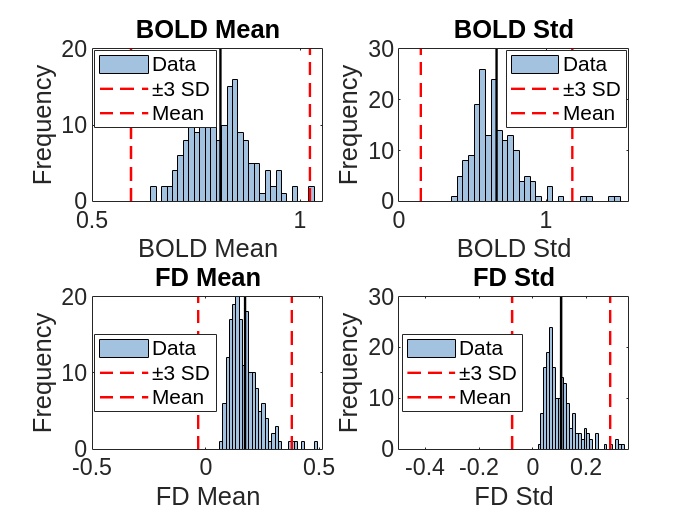

% Section IV = use the QC metrics to identify outliers.
% Use the results_table from your previous loop

% List of variable names in results_table
variables = {'bold_means', 'bold_stds', 'fd_means', 'fd_stds'};

% Create a figure with 2x2 subplots
figure;
for i = 1:length(variables)
        subplot(2, 2, i)
        
        % Extract the data
        data = results_table.(variables{i});
        
        % Compute mean and std
        mu = mean(data, 'omitnan');
        sigma = std(data, 'omitnan');
        
        % Plot histogram
        histogram(data, 30, 'FaceColor', [0.4 0.6 0.8], 'EdgeColor', 'k');
        hold on
        
        % Plot vertical lines for ±3 standard deviations
        yLimits = ylim;
        plot([mu-3*sigma mu-3*sigma], yLimits, 'r--', 'LineWidth', 1.5);
        plot([mu+3*sigma mu+3*sigma], yLimits, 'r--', 'LineWidth', 1.5);
        plot([mu mu], yLimits, 'k-', 'LineWidth', 1.5); % mean line
        
        % Labels (prettify variable names for title)
        switch variables{i}
            case 'bold_means'
                var_title = 'BOLD Mean';
            case 'bold_stds'
                var_title = 'BOLD Std';
            case 'fd_means'
                var_title = 'FD Mean';
            case 'fd_stds'
                var_title = 'FD Std';
            otherwise
                var_title = variables{i};
        end
        
        title(var_title, 'Interpreter', 'none');
        xlabel(var_title);
        ylabel('Frequency');
        legend('Data', '±3 SD', 'Mean', 'Location', 'best');
        
        hold off
end

%% After outliers identified
% Run this if you identify the outliers and re-run the preproc:

% Set the folder
% cd('/nfs/tpolk/mind/Conn_2024/Conn_2025/Prep/W1/Functional');
cd('/nfs/tpolk/mind/Conn_2024/Conn_2025/All_W1_JUNE25/All_W1_JUNE25_with_outliers/Functional_Connectivity');

% Get the list of outlier files
outlier_files_1 = dir('art_regression_outliers_aumind*.mat');

% Initialize arrays to store results
subject_ids = {};
num_outliers = [];

% Loop through each file
for i = 1:length(outlier_files_1)
    % Load the data
    file_name = outlier_files_1(i).name;
    data = load(file_name);
    
    % Get the variable name (assuming only one variable per file)
    var_names = fieldnames(data);
    outlier_matrix = data.(var_names{1});
    
    % Extract 'mindo###' or 'mindb###' from the filename
    token = regexp(file_name, 'au(mind[ob]\d+)_run', 'tokens');
    if ~isempty(token)
        subject_id = token{1}{1};
    else
        subject_id = 'unknown';
    end

    % Count the number of outliers (columns)
    n_outliers = size(outlier_matrix, 2);

    % Store
    subject_ids{end+1,1} = subject_id;
    num_outliers(end+1,1) = n_outliers;
end

% Create a summary table
summary_table = table(subject_ids, num_outliers, ...
    'VariableNames', {'SubjectID', 'NumOutliers'});

% Define the subject list to filter
subject_list = {
    'mindo100'
    'mindo105'
    'mindo107'
    'mindo109'
    'mindo116'
    'mindo123'
    'mindo127'
    'mindo129'
    'mindo133'
    'mindo139'
    'mindo144'
    'mindo151'
    'mindo157'
    'mindo160'
    'mindo161'
    'mindo162'
    'mindo163'
    'mindo165'
    'mindo176'
    'mindo178'
    'mindo180'
    'mindo189'
    'mindo195'
    'mindo205'
    'mindo209'
    'mindo213'
    'mindo216'
    'mindo217'
    'mindo227'
    'mindo228'
    'mindo232'
    'mindo235'
    'mindo252'
    'mindo255'
    'mindo256'
    'mindo260'
    'mindo261'
    'mindo270'
    'mindo273'
    'mindo274'
    'mindo292'
};

% Filter the summary table to keep only selected subjects
filtered_summary = summary_table(ismember(summary_table.SubjectID, subject_list), :);

% Display the filtered result
disp(filtered_summary);


% (Assume you already defined 'selected_subjects' earlier)

% Organize the FD and BOLD signal change for each individual

% Set working directory
cd('/nfs/tpolk/mind/Conn_2024/Conn_2025/Prep/W2/Functional');

% Get all potential files first
all_files = dir('art_regression_timeseries_aumind*.mat');

% Initialize results
subject_ids = {};
bold_means = [];
bold_stds = [];
fd_means = [];
fd_stds = [];

% Loop through each file
for i = 1:length(all_files)
    file_name = all_files(i).name;

    % Only keep files that match *_run_01.mat
    if contains(file_name, '_run_01.mat') && ~isempty(regexp(file_name, 'aumind[ob]\d+', 'once'))
        data = load(file_name);

        % Extract subject ID (e.g., aumindo260 → mindo260)
        token = regexp(file_name, 'aumind[ob]\d+', 'match');
        if ~isempty(token)
            subject_id = extractAfter(token{1}, 2);  % Remove "au"
        else
            subject_id = 'unknown';
        end

        % Extract data matrix
        var_names = fieldnames(data);
        matrix = data.(var_names{1});  % should be 240x2

        % Extract BOLD and FD
        bold_change = matrix(:, 1);
        fd_change = matrix(:, 2);

        % Compute stats
        bold_mean = mean(bold_change);
        bold_std = std(bold_change);
        fd_mean = mean(fd_change);
        fd_std = std(fd_change);

        % Append to lists
        subject_ids{end+1, 1} = subject_id;
        bold_means(end+1, 1) = bold_mean;
        bold_stds(end+1, 1) = bold_std;
        fd_means(end+1, 1) = fd_mean;
        fd_stds(end+1, 1) = fd_std;
    end
end

% Create summary table
summary_table = table(subject_ids, bold_means, bold_stds, fd_means, fd_stds, ...
    'VariableNames', {'SubjectID', 'BOLD_Mean', 'BOLD_Std', 'FD_Mean', 'FD_Std'});

% FILTER based on your existing selected_subjects
filtered_summary = summary_table(ismember(summary_table.SubjectID, subject_list), :);

% Display the filtered result
disp(filtered_summary);


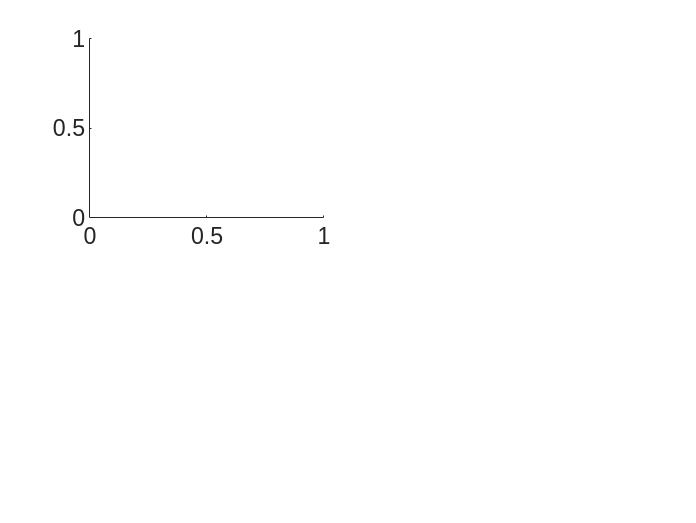

Error using  .  (line 229)
Unrecognized table variable name 'BOLD_Mean'.


% Plot the distribution of the variables in the summary_table
% List of variable names to plot
variables = {'BOLD_Mean', 'BOLD_Std', 'FD_Mean', 'FD_Std'};

% Create a figure with 2x2 subplots
figure;
for i = 1:length(variables)
    subplot(2, 2, i)
    
    % Extract the data
    data = results_table.(variables{i});
    
    % Compute mean and std
    mu = mean(data, 'omitnan');
    sigma = std(data, 'omitnan');
    
    % Plot histogram
    histogram(data, 30, 'FaceColor', [0.4 0.6 0.8], 'EdgeColor', 'k');
    hold on
    
    % Plot vertical lines for ±3 standard deviations
    yLimits = ylim;
    plot([mu-3*sigma mu-3*sigma], yLimits, 'r--', 'LineWidth', 1.5);
    plot([mu+3*sigma mu+3*sigma], yLimits, 'r--', 'LineWidth', 1.5);
    plot([mu mu], yLimits, 'k-', 'LineWidth', 1.5); % mean line
    
    % Labels
    title(variables{i}, 'Interpreter', 'none');
    xlabel(variables{i});
    ylabel('Frequency');
    legend('Data', '±3 SD', 'Mean', 'Location', 'best');
    
    hold off
end


% Improve layout
sgtitle('Distribution of BOLD and FD Measures with ±3 SD');

